clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
s=tf('s');
param.model.Dwz = 100*eye(4);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0.001*eye(4);

listOfUncertainties = {[-1,1]};
% Generates a diagonal matrix for each vertex given the uncertainties.
% Firstly every combination of uncertainties is generated, then
% structured into a 3D array of diagonal matrices.
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end

B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);


A_1 = [param.model.A, param.model.Bw*param.model.Cww, zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,12),param.model.Aww, zeros(4),zeros(4),zeros(4);
         param.model.Bwz*param.model.Cz, -param.model.Bwz*param.model.DWref*param.model.Cww, param.model.Awz, -param.model.Bwz*param.model.CWref,zeros(4);
         zeros(4,12),param.model.BWref*param.model.Cww, zeros(4),param.model.AWref,zeros(4);
         zeros(4,12), zeros(4),zeros(4),zeros(4),param.model.AWu]; 

B_2 = @(k) [B(k);
             zeros(4,4);
             zeros(4,4);
             zeros(4,4);
             param.model.BWu];

B_1 = [param.model.Bw*param.model.Dww;
         param.model.Bww;
         -param.model.Bwz*param.model.DWref*param.model.Dww;
         param.model.BWref*param.model.Dww;
         zeros(4,4)];

C_1 = [param.model.Dwz*param.model.Cz, -param.model.Dwz*param.model.DWref*param.model.Cww, param.model.Cwz,-param.model.Dwz*param.model.CWref,zeros(4);
      zeros(4,12),zeros(4),zeros(4),zeros(4),param.model.CWu];

D_12 = [zeros(4,4);
      param.model.DWu];

D_11 = [-param.model.Dwz*param.model.DWref*param.model.Dww;
        zeros(4,4);];

Q = eye(20);
tol = 1e-2;
tol_alpha = 0.01;
n = param.n;
yalmip('clear')
gamma = 10;
% B_1 = @(k) [B(k); zeros(4,4); zeros(4,4)];
C_2 = [param.model.CySOF, zeros(8,4), zeros(8,4), zeros(8,4), zeros(8,4)];

% B_CL = [param.model.Bw*param.model.Dww; param.model.Bww; -param.model.Bwz*param.model.Dww];
% C_CL = [param.model.Dwz*param.model.Cz, -param.model.Dwz*param.model.Cww, param.model.Cwz];
% D_CL = [-param.model.Dwz*param.model.Dww];

A_bar = [A_1, B_1, zeros(28,8);
        zeros(4,28), -gamma/2*eye(4), zeros(4,8);
        C_1, D_11, -gamma/2*eye(8)];
B_bar = @(k) [B_2(k); zeros(8,4); zeros(4,4)];
C_bar = [C_2, zeros(8,8), D_12];


% Step 1
% [P_bar, ~, P] = constructVariables(param);
% p = cell(1,param.n);
% for i=1:param.n
%     p{i} = sdpvar(3);
% end
% P = sdpvar(20);
% P(1:12,1:12) = blkdiag(p{1:end})
% constraints = [];
% for k=1:length(Uncertainties)
%     constraints = [constraints, [A_1.' * P + P * A_1 + Q, P * B_1(k); B_1(k).' * P, eye(n)] >= 0];
% end
% constraints = [constraints, P >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, -trace(P), options)
yalmip('clear')
q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q = blkdiag(q{:});
Y = blkdiag(y{:});

% Setup constraint
constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, param.model.A * Q + Q * param.model.A.' + param.model.B * (eye(4) + Uncertainties(i) * param.model.Dwd) * Y + Y.' * (eye(4) + Uncertainties(i) * param.model.Dwd)' * param.model.B.' <= 0];
end
% constraints = [constraints,  Q - eye(12) >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, trace(Q), options)
constraints = [constraints,  Q >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options);

X(:,:,1) = blkdiag(inv(value(Q)),eye(28));
i = 1;

while 1
    % Step 2
    yalmip('clear')
    [P_bar, Ksof] = constructVariables(param);
    
    alpha = sdpvar(1);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A_bar.'*P_bar + P_bar*A_bar - X(:,:,i)*(B_bar(k)*B_bar(k).')*P_bar - P_bar*(B_bar(k)*B_bar(k).')*X(:,:,i) + X(:,:,i)*(B_bar(k)*B_bar(k).')*X(:,:,i) - alpha*P_bar , (B_bar(k).'*P_bar + Ksof*C_bar).';
                        (B_bar(k).'*P_bar + Ksof*C_bar), -eye(n)] <= 0];
    end
    constraints = [constraints, P_bar >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = bisection(constraints, alpha, options);
    alpha_min(i) = value(alpha);
    alpha_min(i)
    % Step 3
    if(alpha_min(i) <= tol_alpha)
        break
    end
    if (isnan(alpha_min(i)))
        fprintf("Alpha became NaN after %i itr. Last value was %f \n", i, alpha_min(i-1));
        Ksof = Ksof_Last;
        break
    end
    Ksof_Last = value(Ksof); % Not part of algorithm, used to store last value in case alpha becomes NaN
    % Step 4
    yalmip('clear')
    [P_bar, Ksof] = constructVariables(param);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A_bar.'*P_bar + P_bar*A_bar - X(:,:,i)*(B_bar(k)*B_bar(k).')*P_bar - P_bar*(B_bar(k)*B_bar(k).')*X(:,:,i) + X(:,:,i)*(B_bar(k)*B_bar(k).')*X(:,:,i) - alpha_min(i)*P_bar , (B_bar(k).'*P_bar + Ksof*C_bar).';
                        (B_bar(k).'*P_bar + Ksof*C_bar), -eye(n)] <= 0];
    end
    constraints = [constraints, P_bar >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = optimize(constraints, trace(P_bar), options);
    P_min(:,:,i) = value(P_bar);
    % Step 5
    if (norm(X(:,:,i) - P_min(:,:,i)) < tol)
        % Step 6
        fprintf("Couldn't find a stabilizing solution")
        break
    else
        i = i + 1;
        X(:,:,i) = P_min(:,:,i-1);
    end
end

ans = 5.7764

ans = 3.1730

ans = 2.2277

ans = 1.7002

ans = 1.3566

ans = 1.1164

ans = 0.9370

ans = 0.7966

ans = 0.6827

ans = 0.5879

ans = 0.5074

ans = 0.4378

ans = 0.3768

ans = 0.3229

ans = 0.2748

ans = 0.2315

ans = 0.1924

ans = 0.1568

ans = 0.1242

ans = 0.0943

ans = 0.0669

ans = 0.0416

ans = 0.0182

ans = -0.0034


Ksof = value(Ksof);
Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end

% Evaluation of the results from the design procedure
fprintf("Evaluation of design procedure for ILMI SOF \n")

Evaluation of design procedure for ILMI SOF 


fprintf("Gamma is found to be: %f \n", value(gamma))

Gamma is found to be: 10.000000 


if(eig(param.model.A+param.model.B_Bar*Ksof*param.model.CySOF) > 0)
    fprintf("One or more eigenvalues in the decoupled system is positive!!! \n")
else
    fprintf("Eigenvalues of the decoupled systems are all negative \n")
end

Eigenvalues of the decoupled systems are all negative 


eig(param.model.A+param.model.B_Bar*Ksof*param.model.CySOF).'

ans =   -2.4501 + 0.0000i  -1.5623 + 0.0000i  -0.0246 + 0.0000i  -2.0219 + 1.3888i  -2.0219 - 1.3888i  -0.0316 + 0.0000i  -2.0019 + 1.7031i  -2.0019 - 1.7031i  -0.0333 + 0.0000i  -2.0021 + 1.4523i  -2.0021 - 1.4523i  -0.0327 + 0.0000i



if(eig(param.model.A+param.model.B*Ksof*param.model.CySOF) > 0)
    fprintf("One or more eigenvalues in the coupled system is positive!!! \n")
else
    fprintf("Eigenvalues of the coupled systems are all negative \n")
end

Eigenvalues of the coupled systems are all negative 


eig(param.model.A+param.model.B*Ksof*param.model.CySOF).'

ans =   -2.0064 + 1.9717i  -2.0064 - 1.9717i  -2.0080 + 2.7891i  -2.0080 - 2.7891i  -2.0024 + 3.4892i  -2.0024 - 3.4892i  -2.0152 + 3.1696i  -2.0152 - 3.1696i  -0.0247 + 0.0000i  -0.0316 + 0.0000i  -0.0333 + 0.0000i  -0.0327 + 0.0000i


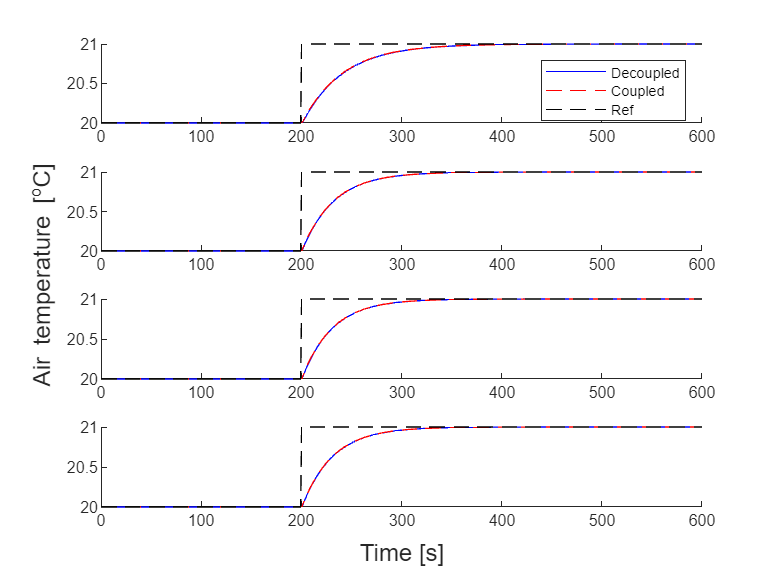

%saves the block version of K this is used further in some simulations
param.ctrl.K = Ksof*param.model.CySOF;
%saves a 3d matrix version of Ks this is used in the simulation of the
%nonlinear system.
param.ctrl.Ks = Ks;


util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI_Hinf",0);

function [P_bar, Ksof, P] = constructVariables(param)
    ksof = cell(1,param.n);
    p = cell(1,param.n);
    for i=1:param.n
        p{i} = sdpvar(3);
        ksof{i} = sdpvar(1,2,'full');
    end
    P = sdpvar(32);
    P(1:12,1:12) = blkdiag(p{1:end});
    P_bar = blkdiag(P,eye(4),eye(4));
    Ksof = blkdiag(ksof{:});
end
